# Cone Detection Using Deep Learning for Formula Student Driverless

This demo shows the step by step approach of data labeling, training and deploying a You Only Look Once X (YOLOX) Neural Network [1-3]. You can find a similar workflow of designing, training and deploying a YOLOv2 Network [4-5].

Thanks to the DIAN Racing Team from Tongji University in China for providing the datasets (videos). In order to use the YOLOX object detector, you need to install the Computer Vision Toolbox™ [Automated Visual Inspection Library](https://www.mathworks.com/matlabcentral/fileexchange/116555-computer-vision-toolbox-automated-visual-inspection-library) support package.

close all; clear; clc;

Set the global random state to the default state to ensure a higher reproducibility of results.

rng("default");

## Step 1: Label Data (One-time step)

You need to label the objects of interest (cones) in the dataset (videos) to perform a supervised learning approach. With [Ground Truth Labeler app](https://www.mathworks.com/help/driving/ug/get-started-with-the-ground-truth-labeler.html) or the [Video Labeler app](https://www.mathworks.com/help/vision/ref/videolabeler-app.html) in MATLAB, you can label the objects manually or [by using the in-built algorithms of the app](https://www.youtube.com/watch?v=V2e0cygY9Vg&t=16s) or by [integrating your own custom algorithms within the app](https://www.youtube.com/watch?v=Y36D1fJZkT0). 

We used the Video Labeler app to create the ground truth in this example, but you can achieve the same results with the Ground Truth Labeler app as well. Open the Video Labeler app via 'APPS' toolstrip or type `videoLabeler` in the command window:

% videoLabeler

## 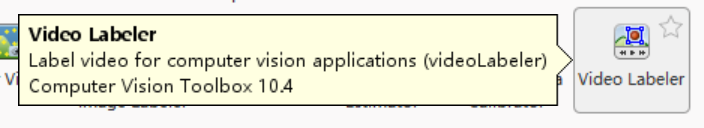

In the Video Labeler app you first need to create labels, and then label the cones frame by frame. Once you have labelled images, you need to export the ground truth as a ground truth data object for each dataset. 

## Step 2: Prepare Data

**Create Datastores**

Convert a saved ground truth object into labeled images.

if (~isfile('dataTable.mat')) ...
    && isfile("gTruthCones.mat") && (~isfolder(fullfile("images")))    

Load a saved ground truth file and change the data source path of the ground truth.

    load("gTruthCones.mat");
    videoPath1 = fullfile(pwd,"videos","video0621.mp4");
    videoPath2 = fullfile(pwd,"videos","video0709.mp4");
    gTruth1 = changeGTruthPath(gTruth1,videoPath1);
    gTruth2 = changeGTruthPath(gTruth2,videoPath2);

Next, create the training data from the ground truth object by using the function objectDetectorTrainingData, and save it for future use.

    mkdir images
    dataTable1 = objectDetectorTrainingData(gTruth1,'SamplingFactor',1,...
        'WriteLocation','images'); % red cones and green cones
    dataTable2 = objectDetectorTrainingData(gTruth2,'SamplingFactor',1,...
        'WriteLocation','images');
    dataTable = [dataTable1;dataTable2];
    save("dataTable.mat","dataTable")
else
    load("dataTable.mat")
end

Display few rows of the data set.

index = 1:5; % You can randomly select 5 using randperm(size(dataTable,1),5);
dataTable(index,:)

Show an example image with labels.

sampleImage = imread(dataTable.imageFilename{index(1),1});
imshow(sampleImage)
showShape("rectangle",dataTable.greenCone{index(1),1},color='green',Label='greenCone');
hold on
showShape("rectangle",dataTable.redCone{index(1),1},color='red',Label='redCone');
hold on
showShape("rectangle",dataTable.yellowConeLeft{index(1),1},color='yellow',Label='yellowConeLeft');
hold on
showShape("rectangle",dataTable.yellowConeRight{index(1),1},color='yellow',Label='yellowConeRight');
title(" Labelled Image Sample")
hold off

Create image and box label datastores.

imds = imageDatastore("images",FileExtensions=".png");
blds = boxLabelDatastore(dataTable(:,2:end));

Combine the image and box label datastores.

ds = combine(imds,blds);

Split the data set into training, validation, and test sets. Because the total number of images is relatively small, allocate a relatively large percentage (70%) of the data for training, and allocate 15% for validation and the rest for testing.

numImages = ds.numpartitions;
numTrain = floor(0.7*numImages);
numVal = floor(0.15*numImages);

shuffledIndices = randperm(numImages);
dsTrain = subset(ds,shuffledIndices(1:numTrain));
dsVal = subset(ds,shuffledIndices(numTrain+1:numTrain+numVal));
dsTest = subset(ds,shuffledIndices(numTrain+numVal+1:end));

**Analyze Data**

- **Object Class Distribution: **Measure the distribution of class labels in the data set by using the [`countEachLabel`](https://ww2.mathworks.cn/help/releases/R2024b/vision/ref/pixellabelimagedatastore.counteachlabel.html) (Computer Vision Toolbox) function.  

countEachLabel(blds)

- **Object Size Distribution: **Display a scatter plot of the object sizes to determine their distribution. 

trainingBoxes = readall(blds);
overallBoxVector = vertcat(trainingBoxes{:,1});
figure
plot(overallBoxVector(:,3),overallBoxVector(:,4),"x")
xlabel("Bounding Box Widths")
ylabel("Bounding Box Heights")

**Augment Training Data**

Augment the training data by using the `augmentData` helper function, which applies these augmentations to the input data:

- Random resizing by a scale factor in the range [1, 1.1]

- Random translation in the horizontal and vertical directions in the range [-50, 50] pixels

dsTrain = transform(dsTrain,@augmentData);

## **Step 3: Create Object Detector **

Create the YOLOX object detector by using the [`yoloxObjectDetector`](docid:vision_ref#mw_9c6e3e1c-638f-42a5-9a77-e539221d5827) (Computer Vision Toolbox) function. Specify pretrained network created using CSP-DarkNet-53 as the base network and trained on the COCO data set [[1](https://ww2.mathworks.cn/help/releases/R2024b/deeplearning/ug/detect-pcb-defects-using-yolox-deep-learning.html#mw_rtc_DetectPCBDefectsUsingYOLOXNetworkExample_M_A8FC53F9)]. 

classNames = categories(blds.LabelData{1,2});
yoloxConeDetector = yoloxObjectDetector("tiny-coco",classNames);

## **Step 4: Specify Training Options**

Specify network training options using the [`trainingOptions`](https://ww2.mathworks.cn/help/releases/R2024b/deeplearning/ref/trainingoptions.html) function. Train the object detector using the SGDM solver for a maximum of 50 epochs. Specify the `ValidationData` as the validation data. Set `OutputNetwork` to `"best-validation-loss"` to obtain the network with the lowest validation loss during training when the training finishes.

options = trainingOptions("sgdm", ...
    InitialLearnRate=5e-4, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.98, ...
    LearnRateDropPeriod=1, ...
    MiniBatchSize=20, ...
    MaxEpochs=50, ...
    ExecutionEnvironment="auto", ...
    Shuffle="every-epoch", ...
    VerboseFrequency=5, ...
    ValidationFrequency=10, ...
    ValidationData=dsVal, ...
    ResetInputNormalization=false, ...
    OutputNetwork="best-validation-loss", ...
    GradientThreshold=30, ...
    L2Regularization=5e-4, ...
    Plots="training-progress");

## Step 5: Train Object Detector

Set the following `doTraining` variable to `true`, and then to train the detector by using the [`trainYOLOXObjectDetector`](https://ww2.mathworks.cn/help/releases/R2024b/vision/ref/trainyoloxobjectdetector.html) (Computer Vision Toolbox) function. Or you can load a pre-trained YOLOX cone detector.

Train on one or more GPUs, if they are available. Using a GPU requires a Parallel Computing Toolbox™ license and a CUDA®-enabled NVIDIA® GPU. For more information, see [GPU Computing Requirements](https://ww2.mathworks.cn/help/releases/R2024b/parallel-computing/gpu-computing-requirements.html) (Parallel Computing Toolbox). Training takes about 16 minutes with a NVIDIA GeForce RTX 4080 Laptop GPU.

doTraining = false;

if doTraining
    [yoloxConeDetector,trainInfo] = trainYOLOXObjectDetector(dsTrain, ...
        yoloxConeDetector,options); 
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm"));
    save(fullfile(pwd,"yoloxConeDetector_"+modelDateTime+".mat"), ...
        "yoloxConeDetector");

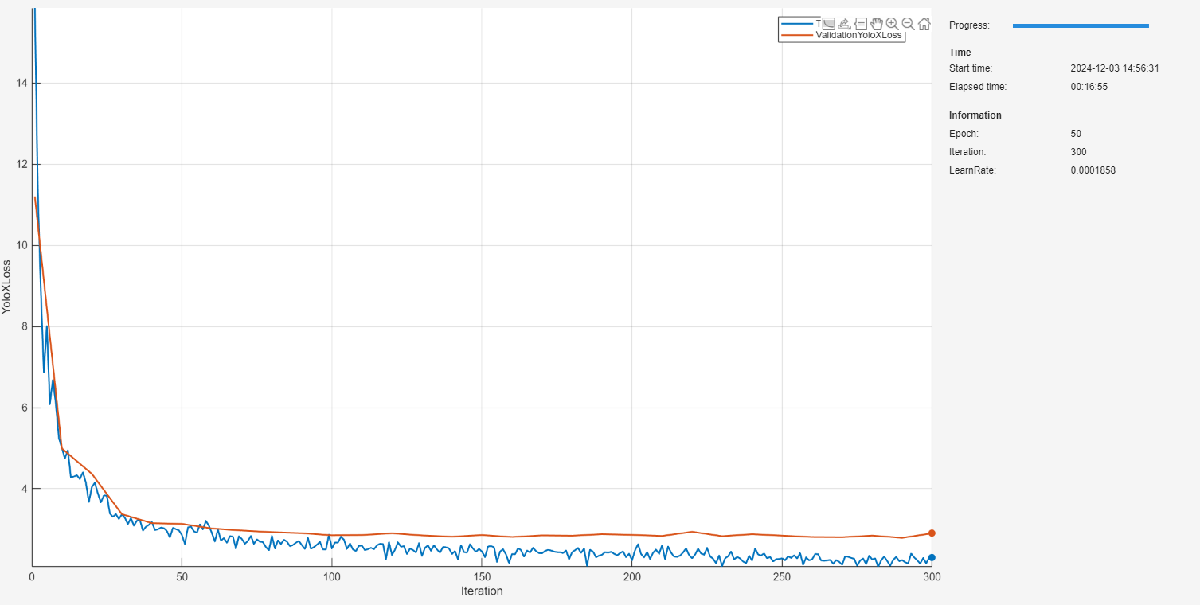

else
    load(fullfile(pwd,"yoloxConeDetector.mat"));
end


## Step 6: Evaluate Object Detector

**Average precision** 

Detect the bounding boxes for all test images. Set the detection threshold to a low value to detect as many objects as possible. This helps you evaluate the detection performance across a full range of detection score values.

detectionResults = detect(yoloxConeDetector,dsTest,Threshold=0.01);

Calculate object detection metrics on the test set detection results.

metrics = evaluateObjectDetection(detectionResults,dsTest);

Calculate and display the average precision (AP) score for each class. Precision quantifies the ability of the detector to classify objects correctly.

AP = averagePrecision(metrics);

### Checking for CUDA availability on the target...
### Checking for 'nvcc' in the target system path...
### Checking for cuDNN library availability on the target...
### Checking for TensorRT library availability on the target...
### Checking for prerequisite libraries is complete.
### Gathering hardware details...
### Checking for third-party library availability on the target...
### Gathering hardware details is complete.
Board name              : NVIDIA Jetson AGX Xavier Developer Kit
CUDA Version            : 11.4
cuDNN Version           : 8.6
TensorRT Version        : 8.5
GStreamer Version       : 1.16.3
V4L2 Version            : 1.18.0-2build1
SDL Version             : 1.2
OpenCV Version          : 4.5.4
Available Webcams       :  
Available GPUs          : Xavier
Available Digital Pins  : 7  11  12  13  15  16  18  19  21  22  23  24  26  29  31  32  33  35  36  37  38  40


table(classNames,AP)

**Precision-Recall**

Calculate the recall and precision values for the detection of each defect object. Recall quantifies the ability of the detector to detect all relevant objects for a class. A precision-recall (PR) curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. Plot the PR curve for the test data.

classNameStrings = metrics.ClassNames;
class = classNames(1);
[precision, recall, ~] = precisionRecall(metrics,ClassName=class);
plot(recall{:},precision{:})
title(sprintf("Average Precision for '" + class + "' Defect: " + "%.2f", ...
    averagePrecision(metrics,ClassName=class)), interpreter="none")
xlabel("Recall")
ylabel("Precision")
grid on

Code generation successful: View report



**Detect Object in a Test Video **

Create video file reader for input

testVideo = fullfile(pwd,'videos','testConeDetector_416x416.mp4');

### Launching the executable on the target...
Executable launched successfully with process ID 20331.
Displaying the simple runtime log for the executable...

Note: For the complete log, run the following command in the MATLAB command window:
system(hwobj,'cat /home/xavier/remoteBuildDir/MATLAB_ws/R2025a/C/MATLAB/cone-detection-using-deep-learning/coneDetection.log')


vidReader = VideoReader(testVideo);

Create video player for visualization.

vidPlayer = vision.DeployableVideoPlayer;

Create an video Object to install the output video.

vidObj = VideoWriter(fullfile(pwd,"testConeDetector_output.mp4"), ...
    'MPEG-4');
open(vidObj);

Detect the cones in each frame of the test video.

while(hasFrame(vidReader))
    % Get Data
    I = readFrame(vidReader);

    % Detect cones
    [bboxes, scores, labels] =  detect(yoloxConeDetector,I,Threshold=0.5);

    % Visulization
    I = insertObjectAnnotation(I,'rectangle',bboxes,labels);
    step(vidPlayer,I);

    %Write to the video object
    writeVideo(vidObj,I);
end

Cleanup the video player and the video object.

release(vidPlayer);
close(vidObj);

## Step 7: Deploy a Object Detector to a GPU

This session shows you how to deploy a trained YOLOX Cone Detector to a Embedded GPU called NVIDIA Jetson™ AGX Xavier [5-6]. 

Create a Jetson object to access the board.

hwobj = jetson('172.18.162.168','xavier','matlab');

 setDisplayEnvironment(hwobj,'1.0')

Configure the coder object:

cfg = coder.gpuConfig('exe');
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/remoteBuildDir';
cfg.GenerateExampleMain = 'GenerateCodeAndCompile';

Use `codegen` to generate the code and a report.

codegen('-config ',cfg,'coneDetection','-report');

Launch the application on Jetson in MATLAB using Jetson objects.

hwobj.runApplication('coneDetection');

Terminate the application on Jetson in MATLAB using Jetson objects.

hwobj.killApplication('coneDetection');

clear hwobj

## `Helper Functions`

`changeGTruthPath `

Change the file path of the data source in the saved ground truth.

function gTruth = changeGTruthPath(gTruth,newPathDS)
oldPathDS = gTruth.DataSource.Source;
alternativePaths = {[oldPathDS  newPathDS]};
changeFilePaths(gTruth,alternativePaths);
end

`augmentData `

The `augmentData` function randomly applies horizontal flipping and scaling to pairs of images and bounding boxes. The function clips boxes outside the bounds if the overlap is above 0.25.

function data = augmentData(A)
data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    % Randomly flip image.
    tform = randomAffine2d(Scale=[1.0 1.1], ...
        XTranslation=[-50, 50],YTranslation=[-50, 50]);
    rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
    I = imwarp(I,tform,OutputView=rout);

    % Apply the same transform to bounding boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
    labels = labels(indices);

    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I bboxes labels};
    end
end
end

## References

[1] Ge, Zheng, Songtao Liu, Feng Wang, Zeming Li, and Jian Sun. "YOLOX: Exceeding YOLO Series in 2021", arXiv, August 6, 2021. [https://arxiv.org/abs/2107.08430.](https://arxiv.org/abs/2107.08430.)

[2] Getting Started with YOLOX for Object Detection: [https://www.mathworks.com/help/vision/ug/getting-started-with-yolox-object-detection.html](https://ww2.mathworks.cn/help/vision/ug/getting-started-with-yolox-object-detection.html)

[3] Detect Defects on Printed Circuit Boards Using YOLOX Network: [https://www.mathworks.com/help/vision/ug/detect-pcb-defects-using-yolox-deep-learning.html](https://www.mathworks.com/help/vision/ug/detect-pcb-defects-using-yolox-deep-learning.html)

[4] YOLOv2 Object Detection: Data Labelling to Neural Networks in MATLAB, [https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab](https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab) 

[5] YOLOv2 Object Detection: Deploy Trained Neural Networks to NVIDIA Embedded GPUs, [https://blogs.mathworks.com/student-lounge/2020/07/22/yolov2-object-detection-deploy-trained-neural-networks-to-nvidia-embedded-gpus/](https://blogs.mathworks.com/student-lounge/2020/07/22/yolov2-object-detection-deploy-trained-neural-networks-to-nvidia-embedded-gpus/) 

[6] Code Generation for Detect Defects on Printed Circuit Boards Using YOLOX Network: [https://ww2.mathworks.cn/help/gpucoder/ug/cuda-code-generation-for-pcb-defect-detection-using-yolox.html](https://ww2.mathworks.cn/help/gpucoder/ug/cuda-code-generation-for-pcb-defect-detection-using-yolox.html)

*Copyright 2025 The MathWorks, Inc.*